# One layer, spherically-symmetric model 

In this notebook the tidal response of **one layer spherically-symmetric model **is computed using LOV3D and compared with results from analytical expressions

clearvars
clc
set(0,'defaulttextInterpreter','latex') 
mfile_name          = mfilename('fullpath');
if contains(mfile_name,'LiveEditorEvaluationHelper')
    mfile_name=matlab.desktop.editor.getActiveFilename;
end
[pathstr,name,ext]  = fileparts(mfile_name);
cd(pathstr);
cd('..')
addpath(genpath(pwd))

## Interior Model 

We consider a one-layer incompressible spherically-symmeric body

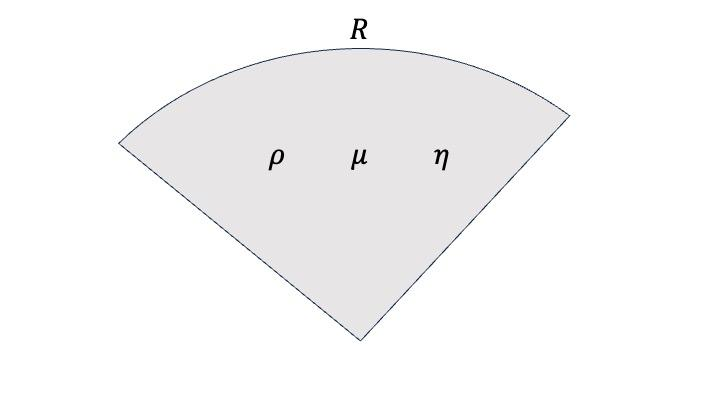

%% Weighted average parameters
% Define the radii (in km)
R0 = 2439.4; % Total radius of the planet
R_core_outer = R0-1326.1; % Outer boundary of the core
R_core_inner = R0-2011.6; % Radius of the inner core

rho0 = 5428.9; % Bulk density

G0 = 6.67430E-11;
T = 87.969*24*3600;% Mercury's orbital period in s


% Mechanical properties
mu_mantle = 65e9; % Average shear modulus of the mantle in Pa (mid-value of 59-71 GPa)
mu_outer_core = 0; % Shear modulus of the outer core in Pa
mu_inner_core = 100e9; % Shear modulus of the inner core in Pa

% Viscosity values (Pa.s)
eta_mantle = 6.41e11; % Assumed viscosity of the mantle in Pa.s (calculated using Andrade model and Steinbrugge values)
eta_outer_core = 0; % Viscosity of the outer core in Pa.s
eta_inner_core = 1e20; % Viscosity of the inner core in Pa.s

% Bulk modulus (assume some average values, adjust as necessary)
K_mantle = 120e9; % Bulk modulus of the mantle in Pa
K_outer_core = 87e9; % Bulk modulus of the outer core in Pa
K_inner_core = 165e9; % Bulk modulus of the inner core in Pa

% Volumes in cubic kilometers
V_mantle = (4/3) * pi * (R0^3 - R_core_outer^3);
V_outer_core = (4/3) * pi * (R_core_outer^3 - R_core_inner^3);
V_inner_core = (4/3) * pi * (R_core_inner^3);
V_total = V_mantle + V_outer_core + V_inner_core;

% Unit test of volume calculation
assert(abs(V_total - 4/3*pi*R0^3)<1e-3)

% % Calculate the weighted average of the bulk density
% rho0_averaged = (V_mantle * rho0_mantle + V_outer_core * rho0_outer_core + V_inner_core * rho0_inner_core) / V_total;

% Calculate weighted averages for shear modulus, viscosity, and bulk modulus
mu0 = (V_mantle * mu_mantle + V_outer_core * mu_outer_core + V_inner_core * mu_inner_core) / V_total;
eta0 = (V_mantle * eta_mantle + V_outer_core * eta_outer_core + V_inner_core * eta_inner_core) / V_total;
K0 = (V_mantle * K_mantle + V_outer_core * K_outer_core + V_inner_core * K_inner_core) / V_total;

mu_eff = mu0 / (rho0^2 * (R0 * 1e3)^2 * 4/3 * pi * G0);

% Print outputs
% fprintf('Weighted Average Bulk Density (rho0_averaged): %e kg/m^3\n', rho0_averaged);
fprintf('Weighted Shear Modulus (mu0): %e Pa\n', mu0);

Weighted Shear Modulus (mu0): 5.936060e+10 Pa


fprintf('Weighted Viscosity (eta0): %e Pa.s\n', eta0);

Weighted Viscosity (eta0): 5.393538e+17 Pa.s


fprintf('Weighted Bulk Modulus (K0): %e Pa\n', K0);

Weighted Bulk Modulus (K0): 1.172838e+11 Pa


% rhodiff = rho0 - rho0_averaged;
% fprintf('rho0-rho0_averaged: %f kg/m^3\n', rhodiff);

% Core layer (1) (small)
Interior_Model(1).R0=1e-3*R0; % CMB radius
Interior_Model(1).rho0=rho0; % Core density 

% Mantle layer (2)
Interior_Model(2).R0=R0;  %surface radius
Interior_Model(2).rho0=rho0;
Interior_Model(2).Ks0=K0; % Bulk modulus
Interior_Model(2).mu0=mu0;  %shear modulus
Interior_Model(2).eta0=eta0;  %viscosity

The forcing potential is defined, note that the degree of the forcing can be changed

Forcing(1).Td=T;
Forcing(1).n=2; 
Forcing(1).m=0; 
Forcing(1).F=1;

## Define numerics used to compute the tidal response 

%radial discretization
Numerics.Nlayers = length(Interior_Model); % number of concentric layers. Including the core!
Numerics.method = 'variable'; % method of setting the radial points per layer
Numerics.Nrbase = 200; % depending on the method this will determine the number of points per layer
%code parallelization
Numerics.parallel_sol = 0; % Use a parfor-loop to call get_Love, either 0 or 1
Numerics.parallel_gen = 0; % Calculate potential coupling files and the propagation inside get_solution using parfor-loops, either 0 or 1
% lateral variations
Numerics.perturbation_order = 2; %maximum order to which couplings are considered
Numerics.solution_cutoff = 12; % maximum degree of solution, not used if perturbation order is specified
Numerics.load_couplings = 1; % 0=no loading, 1=loading of specific file, 2=searches for big enough file
Numerics.Nenergy = 12; % maximum degree to which energy dissipation is expanded 
Numerics.rheology_cutoff = 2; % maximum order of difference (so in log) up to which rheology is still used 
[Numerics, Interior_Model] = set_boundary_indices(Numerics, Interior_Model,'verbose');

Inside set_boundary_indices: 
Nrlayer: 0  200
BCindices: 
Nr: 200
 


## Compare against analytical expression 

The result obtained with the code is compared againts the analytical expression for k2 (see for example [Matsuyama et al. 2018](https://doi.org/10.1016/j.icarus.2018.04.013) Appendix B1)

$k_n=\frac{2}{2(n-1)} \frac{1}{1+\hat\mu_n}$; $h_n=\frac{2n+1}{2(n-1)}\frac{1}{1+\hat\mu_n}$ 

with 

$\hat\mu_n=\frac{2n^2+4n+3}{n}\hat\mu_{eff}$ with  $\hat\mu_{eff}=\frac{\hat\mu}{\rho g R}=\mu_{eff}\left(1-\frac{i}{\hat\tau}\right)^{-1}$

disp('--------------------------')

--------------------------


disp('Viscoelastic solution')

Viscoelastic solution



Interior_Model_ve = get_rheology(Interior_Model,Numerics,Forcing);

No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 


[Love_Spectra,y]=get_Love(Interior_Model_ve,Forcing,Numerics);

% obtain the Fourier-transformed effective shear modulus
mu_eff_hat=mu_eff*Interior_Model_ve(2).muC;
% compute Love numbers using analytical expression
n=Forcing.n; 
mu_n=(2*n^2+4*n+3)/n*mu_eff_hat;
k2_analytic=1/(1+mu_n)*3/2/(n-1);
h2_analytic=1/(1+mu_n)*(2*n+1)/2/(n-1);
% display results
disp(['k Love number analytical expression: ' num2str(k2_analytic)])

k Love number analytical expression: 0.12015-0.014695i


disp(['k Love number LOV3D: ' num2str(Love_Spectra.k)])

k Love number LOV3D: 0.12072-0.014722i


disp(['Normalized difference: ' num2str((Love_Spectra.k-k2_analytic)/k2_analytic*100)  '%'])

Normalized difference: 0.47459+0.035621i%


disp(['h Love number analytical expression: ' num2str(h2_analytic)])

h Love number analytical expression: 0.20024-0.024492i


disp(['h Love number LOV3D: ' num2str(Love_Spectra.h)])

h Love number LOV3D: 0.20881-0.024717i


disp(['Normalized difference: ' num2str((Love_Spectra.h-h2_analytic)/h2_analytic*100)  '%'])

Normalized difference: 4.2291+0.40486i%


disp('--------------------------')

--------------------------


disp('Elastic solution with eta0=0')

Elastic solution with eta0=0


Interior_Model_e = Interior_Model;
Interior_Model_e(2).eta0=[];
Interior_Model_e = get_rheology(Interior_Model_e,Numerics,Forcing);

Viscosity for layer 2 not provided, I will assume the layer is elastic 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 


[Love_Spectra,y]=get_Love(Interior_Model_e,Forcing,Numerics);

% obtain the Fourier-transformed effective shear modulus
mu_eff_hat=mu_eff*Interior_Model_e(2).muC;
% compute Love numbers using analytical expression
n=Forcing.n; 
mu_n=(2*n^2+4*n+3)/n*mu_eff_hat;
k2_analytic=1/(1+mu_n)*3/2/(n-1);
h2_analytic=1/(1+mu_n)*(2*n+1)/2/(n-1);
% display results
disp(['k Love number analytical expression: ' num2str(k2_analytic)])

k Love number analytical expression: 0.11999


disp(['k Love number LOV3D: ' num2str(Love_Spectra.k)])

k Love number LOV3D: 0.12057


disp(['Normalized difference: ' num2str((Love_Spectra.k-k2_analytic)/k2_analytic*100)  '%'])

Normalized difference: 0.47954%


disp(['h Love number analytical expression: ' num2str(h2_analytic)])

h Love number analytical expression: 0.19998


disp(['h Love number LOV3D: ' num2str(Love_Spectra.h)])

h Love number LOV3D: 0.20855


disp(['Normalized difference: ' num2str((Love_Spectra.h-h2_analytic)/h2_analytic*100)  '%'])

Normalized difference: 4.2815%


disp('--------------------------')

--------------------------


disp('Ideal fluid (omega=0)')

Ideal fluid (omega=0)


Interior_Model_i = Interior_Model;
Forcing_i = Forcing;
% Omega=0 so no forcing? -> Td is large (inf doesnt work)
Forcing_i(1).Td=1e12;
% Forcing_i(1).n=[]; 
% Forcing_i(1).m=[]; 
% Forcing_i(1).F=[];

% Ideal fluid model adjustments
% Interior_Model_i(2).mu0 = [];
% Interior_Model_i(2).Ks0 = [];
% Interior_Model_i(2).eta0 = 1e4; % Removing viscosity for a purely elastic response

Interior_Model_i = get_rheology(Interior_Model_i,Numerics,Forcing_i);

No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 


[Love_Spectra,y]=get_Love(Interior_Model_i,Forcing_i,Numerics);

% obtain the Fourier-transformed effective shear modulus
mu_eff_hat=mu_eff*Interior_Model_i(2).muC;

% compute Love numbers using analytical expression
n=Forcing.n; 
mu_n=(2*n^2+4*n+3)/n*mu_eff_hat;
k2_analytic=1/(1+mu_n)*3/2/(n-1);
h2_analytic=1/(1+mu_n)*(2*n+1)/2/(n-1);
% display results
disp(['k Love number analytical expression: ' num2str(k2_analytic)])

k Love number analytical expression: 1.5-0.00098488i


disp(['k Love number LOV3D: ' num2str(Love_Spectra.k)])

k Love number LOV3D: 1.5-0.0012172i


disp(['Normalized difference: ' num2str((Love_Spectra.k-k2_analytic)/k2_analytic*100)  '%'])

Normalized difference: 0.0023096-0.015485i%


disp(['h Love number analytical expression: ' num2str(h2_analytic)])

h Love number analytical expression: 2.5-0.0016415i


disp(['h Love number LOV3D: ' num2str(Love_Spectra.h)])

h Love number LOV3D: 2.5007-0.00324i


disp(['Normalized difference: ' num2str((Love_Spectra.h-h2_analytic)/h2_analytic*100)  '%'])

Normalized difference: 0.028236-0.063924i%


% Analysis of the sensitivity of tidal response to mechanical properties
disp('--------------------------')

--------------------------


disp('Sensitivity Analysis')

Sensitivity Analysis



% Define the range and number of points for shear modulus and viscosity
mu_range = linspace(0.1*mu0, 10*mu0, 5);
eta_range = logspace(-5, 5, 5) * eta0;
[K, ETA] = meshgrid(mu_range, eta_range);

% Initialize arrays to store computed k Love numbers
k_values = zeros(size(K));

% Loop over each pair of shear modulus and viscosity
for i = 1:numel(K)
    % Update the mechanical properties in the interior model
    Interior_Model(2).mu0 = K(i);
    Interior_Model(2).eta0 = ETA(i);
    
    % Compute the tidal response with updated properties
    Interior_Model_updated = get_rheology(Interior_Model, Numerics, Forcing);
    [Love_Spectra, y] = get_Love(Interior_Model_updated, Forcing, Numerics);
    
    % Store the computed k Love number
    k_values(i) = Love_Spectra.k;
end

No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume th

No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 


No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 


No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 


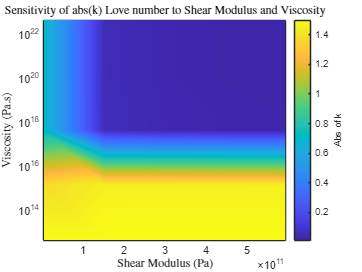

% Plot the results using pcolor
figure;
pcolor(K, ETA, reshape(abs(k_values), size(K)));
set(gca, 'yscale', 'log');
shading interp;
cb=colorbar;
xlabel('Shear Modulus (Pa)');
ylabel('Viscosity (Pa.s)');
ylabel(cb, 'Abs of k')
title('Sensitivity of abs(k) Love number to Shear Modulus and Viscosity');

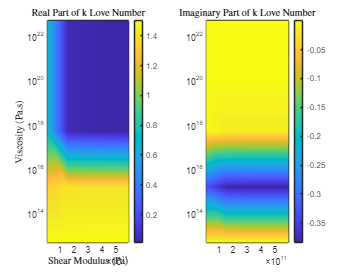

% Extract real and imaginary parts
k_real = real(k_values);
k_imag = imag(k_values);

% Plotting
figure;
subplot(1, 2, 1); % Real part
pcolor(K, ETA, reshape(abs(k_real), size(K)));
set(gca, 'yscale', 'log');
shading interp;
colorbar;
title('Real Part of k Love Number');
xlabel('Shear Modulus (Pa)');
ylabel('Viscosity (Pa.s)');

subplot(1, 2, 2); % Imaginary part
pcolor(K, ETA, reshape(k_imag, size(K)));
set(gca, 'yscale', 'log');
shading interp;
colorbar;
title('Imaginary Part of k Love Number');